**Let's assume y = 0.5e^(0.1x) + 2.    Let's plot this function from x = 0 to 40**

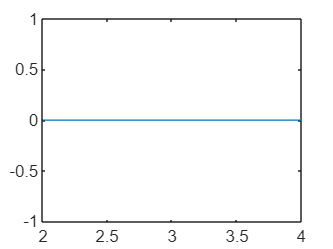

xx = 2 : 1 : 4;
yy = xx.^5 - 16*xx.^4 + 99*xx.^3 - 296*xx.^2 + 428*xx - 240 ;
plot(xx,yy,'-')

**Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use linear interpolation (a first-order Lagrange polynomial) to predict the unknown function**

x = linspace(2,3,2) ;
y = x.^5 - 16*x.^4 + 99*x.^3 - 296*x.^2 + 428*x - 240 ;
yy1 = Lagrange(x,y,xx);


L1 = 1.0000
L1 = -0.0000
L1 = -1.0000
L2 = 0.0000
L2 = 1.0000
L2 = 2.0000
et = 100.0000
et = 100.0000
et = 100.0000


L1 =      1     0    -1


L2 =      0     1     2


et =    100   100   100


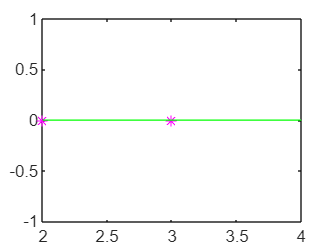


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy1,"-g")
hold off


xtest = 2.5;
y_pred = Lagrange(x,y,xtest)

y_pred = 0

et = abs()

**Now assume that we only know 3 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a second-order Lagrange  polynomial) to predict the unknown function**

x = linspace(2,3.5,3) ;
y = x.^5 - 16*x.^4 + 99*x.^3 - 296*x.^2 + 428*x - 240 ;
yy2 = Lagrange(x,y,xx);

L1 = 1.0000
L1 = -0.1111
L1 = 0.5556
L2 = 0.0000
L2 = 0.8889
L2 = -1.7778
et = 100.0000
et = 65.0000
et = 650.0000


L1 =     1.0000   -0.1111    0.5556


L2 =          0    0.8889   -1.7778


et =    100    65   650


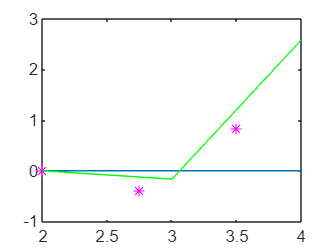


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy2,"-g")
hold off


xtest = 2.5;
y_pred = Lagrange(x,y,xtest)

y_pred = -0.4453

**Now assume that we only know 4 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a 3th-order Lagrange  polynomial) to predict the unknown function**

x = linspace(2,4,4) ;
y = x.^5 - 16*x.^4 + 99*x.^3 - 296*x.^2 + 428*x - 240 ;
yy3 = Lagrange(x,y,xx);

L1 = 1.0000
L1 = -0.0625
L1 = -0.0000
L2 = 0.0000
L2 = 0.5625
L2 = 0.0000
et = 100.0000
et = 123.7037
et = 100.0000


L1 =     1.0000   -0.0625         0


L2 =          0    0.5625         0


et =   100.0000  123.7037  100.0000


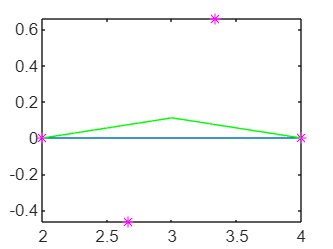


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy3,"-g")
hold off


xtest = 2.5;
y_pred = Lagrange(x,y,xtest)

y_pred = -0.6250